%Initializing the values for computation
R = 0.05;
H = 4.0;
K = 0.95;
Fh = 0.3;
Tr = 8.0;
D = 1.0;

Ps = 0.3; %Initializing the P-step value


%Initializing t and s
t = sym('t')

$$t = t$$

s = sym('s')

$$s = s$$

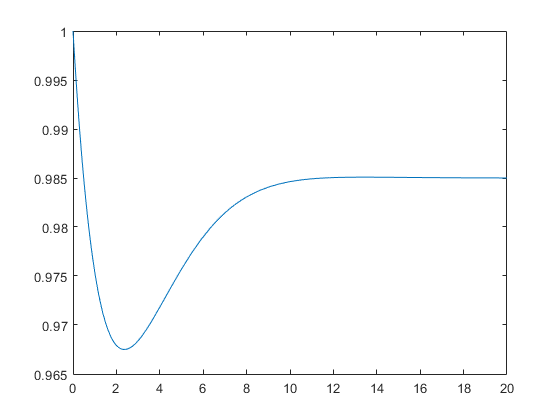


%Calculating  𝜔𝑛 
wn2 = (D*R+K)/(2*H*R*Tr);
wn = sqrt(wn2);

%Calculating  𝜁 
c = (((2*H*R)+(((D*R)+(K*Fh))*Tr))/(2*(D*R+K)))*wn ;


%Calculating alpha
a = sqrt((1-2*Tr*c*wn+(Tr^2)*(wn^2))/(1-(c^2)));

%Calculating 𝜔r
wr = wn*(sqrt(1-(c^2)));

%Calculating the angle (In Radians)
phi = atan((wr*Tr)/(1-c*wn*Tr))-atan(sqrt(1-(c^2))/(-c));


ft = 1 - ((R*Ps)/(D*R+K))*(1+a*exp(-c*wn*t)*sin(wr*t+phi));
fplot(ft, [0 20])
xlim([0 20])
ylim([0.965 1])


%Defining the frequency Nadir
fs = 1 - ((R*Ps)/(D*R+K));
tn = (1/wr)*atan((wr*Tr)/(c*wn*Tr-1));
fn = 1 - ((R*Ps)/(D*R+K))*(1+a*exp(-c*wn*tn)*sin(wr*tn+phi));

%Declare the correction Factor
B = 0.8;
Dtr = fs - fn;
%The new frequency Nadir with the correction Factor
fnew = B*Dtr + fn;


%Declare and compute Tau and Tau2
sympref('HeavisideAtOrigin',1);
tau = vpasolve(ft-(B*Dtr+fn)==0,t)

$$tau = 0.64850059178443801858717064354481$$

%tau2 = vpasolve(ft-(B*Dtr+fn)==0,t,4)

$$tau2 = 7.0294249087066162204973329548659$$

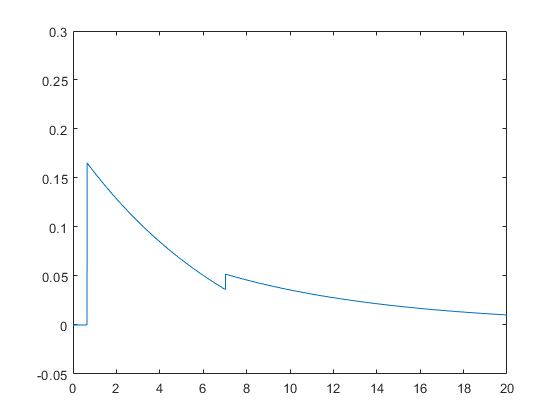



%Define the function Delta Frequency, and plot in the time domain
%fplot(heaviside(t-tau)-heaviside(t-tau2),[0 10])
dft = vpa(fnew - ft)*(heaviside(t-tau) ); %- heaviside(t-tau2)
% fplot(dft)
% xlim([0 20])
% ylim([-0.01 0.03])


%final equation to get power injection
dFs = laplace(dft);

GSFR = ((R*(wn^2))/(D*R+K))*((1+Tr*s)/((s^2)+2*c*wn*s+(wn^2)));

dPs = dFs/GSFR;
dpt = ilaplace(dPs);
 
 
fplot(dpt, [0 20])
xlim([0 20])
ylim([-0.05 0.3])